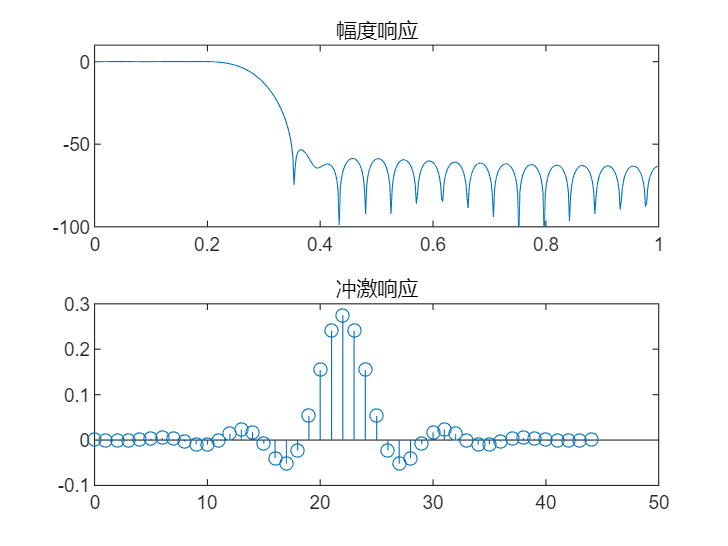


clf%设计FIR滤波器,选择汉明窗
wp=0.2*pi;ws=0.35*pi;
deltaw=ws-wp;
N0=ceil(6.6*pi/deltaw);   %选择汉明窗，求滤波器长度N0
N=N0+mod(N0+1,2);    %选择1型滤波器，确保N为奇数
alfa=(N-1)/2;
wc=(wp+ws)/2;
windows=hamming(N);  %汉明窗
n=0:N-1;
hd=sin(wc*(n-alfa+eps))./(pi*(n-alfa+eps));   
h=hd.*windows';
subplot(2,1,2);stem(n,h); title('冲激响应');
[H,w]=freqz(h,1);
subplot(2,1,1);plot(w/pi,20*log10(abs(H)/abs(H(1))));  title('幅度响应');
axis([0,1,-100,10]);

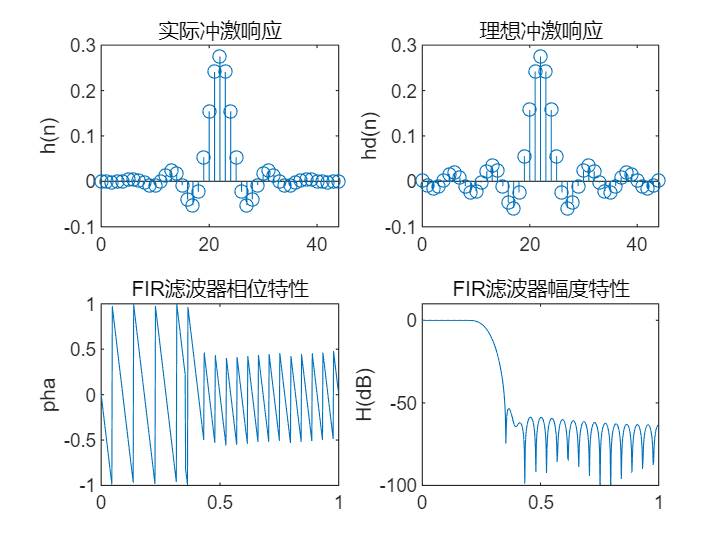


clf%FIR滤波器幅度特性和相位特性
wp=0.2*pi;ws=0.35*pi;
deltaw=ws-wp;
N0=ceil(6.6*pi/deltaw);  
N=N0+mod(N0+1,2);   
alfa=(N-1)/2;
wc=(wp+ws)/2;
windows=hamming(N);  %汉明窗
n=0:N-1;
hd=sin(wc*(n-alfa+eps))./(pi*(n-alfa+eps)); 
h=hd.*windows'; 
[H,w]=freqz(h,1);
subplot(2,2,2);stem(n,hd); axis([0,N-1,-0.1,0.3]);title('理想冲激响应');ylabel('hd(n)');
subplot(2,2,1);stem(n,h);  axis([0,N-1,-0.1,0.3]);title('实际冲激响应');ylabel('h(n)');
subplot(2,2,4);plot(w/pi,20*log10(abs(H)/abs(H(1))));  
axis([0,1,-100,10]); title('FIR滤波器幅度特性');ylabel('H(dB)');
subplot(2,2,3);plot(w/pi,angle(H)/pi); title('FIR滤波器相位特性'); ylabel('pha'); %相位特性

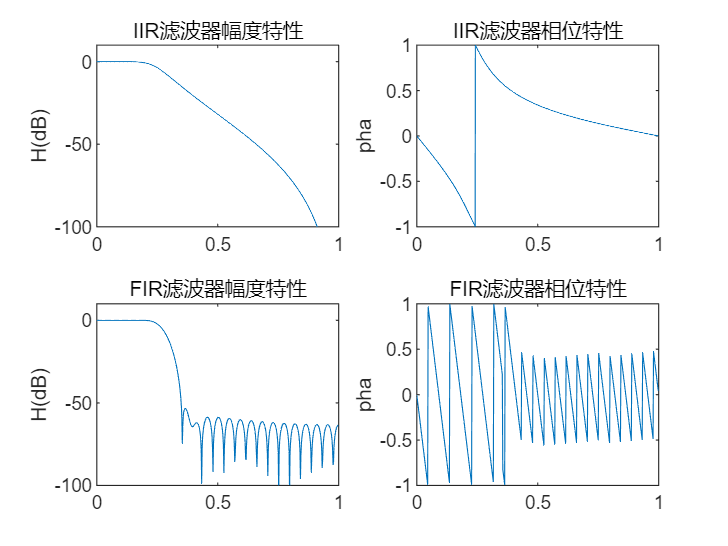


clf%比较IIR滤波器和FIR滤波器的幅度特性和相位特性
%IIR滤波器设计
wp=0.2;ws=0.35;Ap=1;As=15;
[N,fc]=buttord(wp,ws,Ap,As);    
[b,a]=butter(N,fc);           
[h,w]=freqz(b,a,1024);          
subplot(2,2,1);plot(w/pi,20*log10(abs(h)/abs(h(1))));title('IIR滤波器幅度特性');ylabel('H(dB)');
axis([0,1,-100,10]);
subplot(2,2,2);plot(w/pi,angle(h)/pi);title('IIR滤波器相位特性');ylabel('pha');
axis([0,1,-1,1]);
%FIR滤波器设计
wp=0.2*pi;ws=0.35*pi;
deltaw=ws-wp;
N0=ceil(6.6*pi/deltaw);  
N=N0+mod(N0+1,2);   
alfa=(N-1)/2;
wc=(wp+ws)/2;
windows=hamming(N);  %汉明窗
n=0:N-1;
hd=sin(wc*(n-alfa+eps))./(pi*(n-alfa+eps));   
h=hd.*windows'; 
[H,w]=freqz(h,1);
subplot(2,2,3);plot(w/pi,20*log10(abs(H)/abs(H(1)))); 
title('FIR滤波器幅度特性');ylabel('H(dB)');axis([0,1,-100,10]); 
subplot(2,2,4);plot(w/pi,angle(H)/pi); title('FIR滤波器相位特性'); ylabel('pha');  

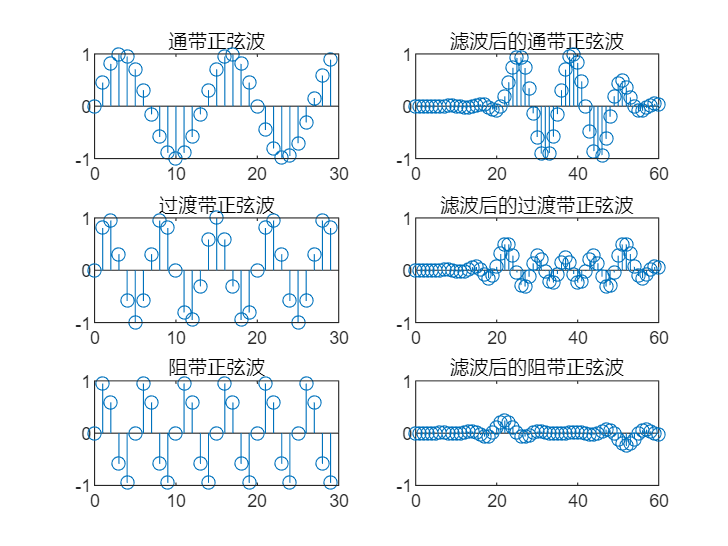


clf%实现FIR不同频率正弦波的数字滤波
wp=0.2*pi;ws=0.35*pi;
deltaw=ws-wp;
N0=ceil(6.6*pi/deltaw);   %汉明窗
N=N0+mod(N0+1,2);    %1型滤波器
alfa=(N-1)/2;
wc=(wp+ws)/2;
windows=hamming(N);  %汉明窗
n=0:N-1;
hd=sin(wc*(n-alfa+eps))./(pi*(n-alfa+eps));  
h=hd.*windows';      %冲激响应
w1=0.15*pi;w2=0.3*pi;w3=0.4*pi;
n1=0:29;
x1=sin(w1.*n1);x2=sin(w2.*n1);x3=sin(w3.*n1); %正弦波频率:通带、过渡带、阻带
figure
subplot(3,2,1);   stem(n1,x1); title('通带正弦波'); %原通带正弦波
subplot(3,2,2);   y1=conv(x1,h); stem(0:length(y1)-1,y1);axis([0,60,-1,1]); title('滤波后的通带正弦波'); 
subplot(3,2,3);   stem(n1,x2); title('过渡带正弦波'); %原过渡带正弦波   
subplot(3,2,4);   y2=conv(x2,h); stem(0:length(y2)-1,y2);axis([0,60,-1,1]); title('滤波后的过渡带正弦波'); 
subplot(3,2,5);   stem(n1,x3); title('阻带正弦波');  %原阻带正弦波
subplot(3,2,6);   y3=conv(x3,h); stem(0:length(y3)-1,y3);axis([0,60,-1,1]); title('滤波后的阻带正弦波'); 

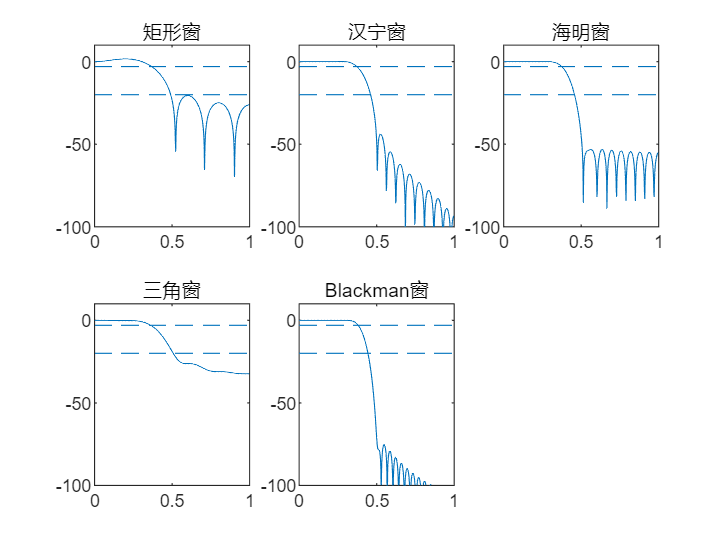


clf%分别用矩形窗、汉宁窗、海明窗、三角窗和Blackman窗设计FIR滤波器，标出3dB和20dB带宽
wp=0.3*pi;ws=0.5*pi;
deltaw=ws-wp;wc=(wp+ws)/2;
for i=1:5
    switch i
        case 1
            N0=ceil(1.8*pi/deltaw);   %选择矩形窗，求滤波器长度N0
            N=N0+mod(N0+1,2);   %选择1型滤波器，确保N为奇数
            windows=boxcar(N);  %矩形窗
        case 2
            N0=ceil(6.2*pi/deltaw);   %选择汉宁窗，求滤波器长度N0
            N=N0+mod(N0+1,2);    %选择1型滤波器，确保N为奇数
            windows=hanning(N);  %汉宁窗
        case 3
            N0=ceil(6.6*pi/deltaw);   %选择海明窗，求滤波器长度N0
            N=N0+mod(N0+1,2);    %选择1型滤波器，确保N为奇数
            windows=hamming(N);  %海明窗
        case 4
            N0=ceil(4.2*pi/deltaw);   %选择三角窗，求滤波器长度N0
            N=N0+mod(N0+1,2);    %选择1型滤波器，确保N为奇数
            windows=bartlett(N);  %三角窗
        case 5
            N0=ceil(11*pi/deltaw);   %选择Blackman窗，求滤波器长度N0
            N=N0+mod(N0+1,2);    %选择1型滤波器，确保N为奇数
            windows=blackman(N);  %Blackman窗
    end
alfa=(N-1)/2;
n=0:N-1;
hd=sin(wc*(n-alfa+eps))./(pi*(n-alfa+eps));   %eps微小值，避免0作除数
h=hd.*windows';
[H,w]=freqz(h,1);
subplot(2,3,i);plot(w/pi,20*log10(abs(H)/abs(H(1))));axis([0,1,-100,10]);
line([0,1],[-3,-3],'linestyle','--');
line([0,1],[-20,-20],'linestyle','--');
switch i
    case 1
        title('矩形窗');
    case 2
        title('汉宁窗');
    case 3
        title('海明窗');
    case 4
        title('三角窗');
    case 5
        title('Blackman窗');
end
end